clc; clear; close all;

%% ===== DEMO PRINCIPAL =====
rng(12345);
M = randi([0 1], 8, 8);

%% ===== ATRACTOR DE CHEN =====
x0 = -10.1234; y0 = 0.5678; z0 = 20.4321;
N0 = 10000; N = 3;

[rawX, rawY, rawZ] = chenRaw(x0, y0, z0, N0, N);
chaosVals = [rawX(1), rawY(1), rawZ(1)];
[automatas, iteraciones] = deriveAutomataAndIterations(chaosVals);

disp(sprintf('--- Valores caoticos brutos ---'));

--- Valores caoticos brutos ---


disp(sprintf('  x = %.10f', chaosVals(1)));

  x = -4.8714584608


disp(sprintf('  y = %.10f', chaosVals(2)));

  y = -6.5634020487


disp(sprintf('  z = %.10f', chaosVals(3)));

  z = 15.0609236927


disp(sprintf('--- Parametros derivados ---'));

--- Parametros derivados ---


disp(sprintf('  Automatas:   %d  %d  %d', automatas(1), automatas(2), automatas(3)));

  Automatas:   7  3  12


disp(sprintf('  Iteraciones: %d  %d  %d', iteraciones(1), iteraciones(2), iteraciones(3)));

  Iteraciones: 1  3  6



rules = getCompositeRuleTable();
for k = 1:3
    disp(sprintf('  Automata %d -> enc="%s"  dec="%s"', ...
        automatas(k), rules(automatas(k)+1).enc, rules(automatas(k)+1).dec));
end

  Automata 7 -> enc="cCCcccCC"  dec="AaAAaaaA"
  Automata 3 -> enc="aaAAAaaA"  dec="cCCCccCc"
  Automata 12 -> enc="bcACAbbB"  dec="bCaCAbbB"


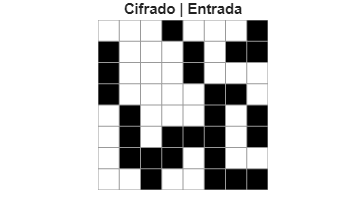

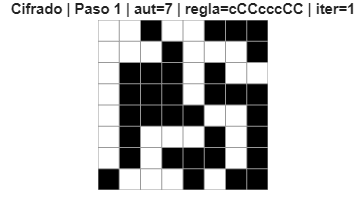

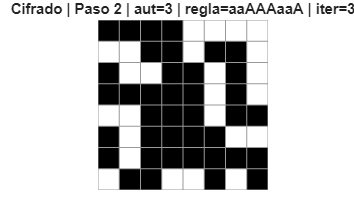

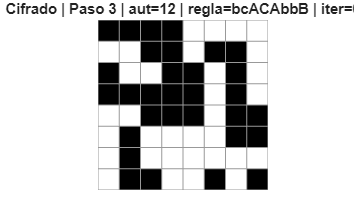


%% ===== CIFRADO =====
C = aplicarTresAutomatas(M, automatas, iteraciones, true, true);

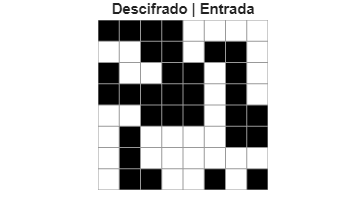

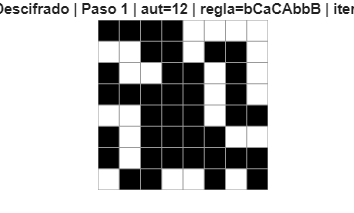

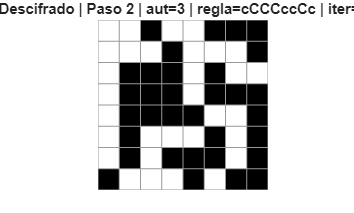

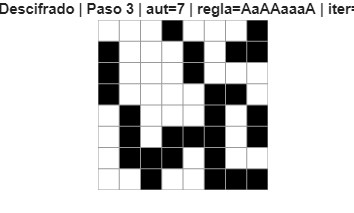


%% ===== DESCIFRADO =====
D = aplicarTresAutomatas(C, automatas, iteraciones, false, true);


disp(sprintf('Recuperacion exacta: %d', isequal(M, D)));

Recuperacion exacta: 1


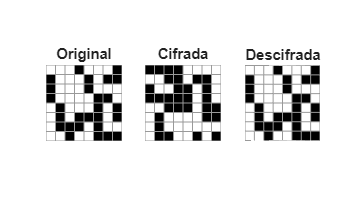


%% ===== VISUALIZACIÓN FINAL =====
figure('Name', 'Resultado Final', 'NumberTitle', 'off');
subplot(1,3,1); mostrarBinaria(M, 'Original');
subplot(1,3,2); mostrarBinaria(C, 'Cifrada');
subplot(1,3,3); mostrarBinaria(D, 'Descifrada');


%% =====================================================================
%% FUNCIONES LOCALES
%% =====================================================================

function mostrarBinaria(M, titulo)
    imagesc(double(M));
    colormap(gray);
    clim([0 1]);
    axis image off;
    title(titulo, 'FontSize', 11);
    [R, C] = size(M);
    hold on;
    for j = 0.5:1:C+0.5
        plot([j j], [0.5 R+0.5], 'Color', [0.6 0.6 0.6], 'LineWidth', 0.8);
    end
    for i = 0.5:1:R+0.5
        plot([0.5 C+0.5], [i i], 'Color', [0.6 0.6 0.6], 'LineWidth', 0.8);
    end
    hold off;
end

function Mout = aplicarTresAutomatas(M, automatas, iteraciones, encryptMode, verbose)
    if nargin < 5, verbose = false; end
    rules      = getCompositeRuleTable();
    recorr     = {'col_up_lr', 'row_lr', 'col_up_rl'};
    Mout       = M;
    applyOrder = 1:3;
    if ~encryptMode, applyOrder = 3:-1:1; end
    modeStr = 'Cifrado';
    if ~encryptMode, modeStr = 'Descifrado'; end

    if verbose
        figure('Name', [modeStr ' | Paso 0 - Entrada'], 'NumberTitle', 'off');
        mostrarBinaria(Mout, [modeStr ' | Entrada']);
    end

    for idx = 1:3
        i   = applyOrder(idx);
        aid = automatas(i);
        t   = iteraciones(i);
        if encryptMode
            rule = rules(aid+1).enc;
        else
            rule = rules(aid+1).dec;
        end
        Mout = applyAutomatonByLines(Mout, rule, t, recorr{i});
        if verbose
            tituloStr = sprintf('%s | Paso %d | aut=%d | regla=%s | iter=%d', ...
                                modeStr, idx, aid, rule, t);
            figure('Name', tituloStr, 'NumberTitle', 'off');
            mostrarBinaria(Mout, tituloStr);
        end
    end
end

function [rawX, rawY, rawZ] = chenRaw(x0, y0, z0, N0, N)
    a = 35; b = 3; c = 28; dt = 0.001;
    x = x0; y = y0; z = z0;
    for k = 1:N0
        [x,y,z] = rk4step_chen(x, y, z, a, b, c, dt);
    end
    rawX = zeros(1,N); rawY = zeros(1,N); rawZ = zeros(1,N);
    for k = 1:N
        [x,y,z] = rk4step_chen(x, y, z, a, b, c, dt);
        rawX(k) = x; rawY(k) = y; rawZ(k) = z;
    end
end

function [xn, yn, zn] = rk4step_chen(xi, yi, zi, a, b, c, dt)
    f  = @(xx,yy,zz) [a*(yy-xx); (c-a)*xx - xx*zz + c*yy; xx*yy - b*zz];
    k1 = f(xi, yi, zi);
    k2 = f(xi+dt/2*k1(1), yi+dt/2*k1(2), zi+dt/2*k1(3));
    k3 = f(xi+dt/2*k2(1), yi+dt/2*k2(2), zi+dt/2*k2(3));
    k4 = f(xi+dt*k3(1),   yi+dt*k3(2),   zi+dt*k3(3));
    dv = (k1+2*k2+2*k3+k4)/6;
    xn = xi+dt*dv(1); yn = yi+dt*dv(2); zn = zi+dt*dv(3);
end

function [automatas, iteraciones] = deriveAutomataAndIterations(vals)
    n = numel(vals);
    automatas   = zeros(1,n);
    iteraciones = zeros(1,n);
    for i = 1:n
        v    = abs(vals(i));
        frac = v - floor(v);
        automatas(i) = mod(floor(frac * 1000), 16);
        d1 = floor(frac * 10);
        d2 = floor(frac * 100)  - d1*10;
        d3 = floor(frac * 1000) - floor(frac*100)*10;
        if     d3 ~= 0, iteraciones(i) = d3;
        elseif d2 ~= 0, iteraciones(i) = d2;
        elseif d1 ~= 0, iteraciones(i) = d1;
        else,           iteraciones(i) = 1;
        end
    end
end

function M = applyAutomatonByLines(M, compRule, times, pathType)
    [R, C] = size(M);
    for t = 1:times
        switch pathType
            case 'col_up_lr'
                buf = zeros(1, R*C); pos = 1;
                for j = 1:C
                    buf(pos:pos+R-1) = M(R:-1:1, j); pos = pos+R;
                end
                buf = processBuffer(buf, compRule);
                pos = 1;
                for j = 1:C
                    M(R:-1:1, j) = buf(pos:pos+R-1); pos = pos+R;
                end
            case 'row_lr'
                buf = zeros(1, R*C); pos = 1;
                for i = 1:R
                    buf(pos:pos+C-1) = M(i, :); pos = pos+C;
                end
                buf = processBuffer(buf, compRule);
                pos = 1;
                for i = 1:R
                    M(i, :) = buf(pos:pos+C-1); pos = pos+C;
                end
            case 'col_up_rl'
                buf = zeros(1, R*C); pos = 1;
                for j = C:-1:1
                    buf(pos:pos+R-1) = M(R:-1:1, j); pos = pos+R;
                end
                buf = processBuffer(buf, compRule);
                pos = 1;
                for j = C:-1:1
                    M(R:-1:1, j) = buf(pos:pos+R-1); pos = pos+R;
                end
            otherwise
                error('Recorrido desconocido: %s', pathType);
        end
    end
end

function buf = processBuffer(buf, compRule)
    L         = numel(buf);
    numBlocks = floor(L / 8);
    original  = buf;
    for b = 1:numBlocks
        i0   = (b-1)*8 + 1;
        idxs = mod((i0-1):(i0+6), L) + 1;
        buf(idxs) = evolveOnce(original(idxs), compRule);
    end
end

function ns = evolveOnce(state, rule)
    n  = numel(state);
    ns = zeros(1, n);
    for i = 1:n
        Lv = state(mod(i-2,n)+1);
        Sv = state(i);
        Rv = state(mod(i,  n)+1);
        ns(i) = applySymbol(Lv, Sv, Rv, rule(i));
    end
end

function out = applySymbol(L, S, R, sym)
    switch sym
        case 'A', out = L;
        case 'B', out = S;
        case 'C', out = R;
        case 'a', out = 1 - L;
        case 'b', out = 1 - S;
        case 'c', out = 1 - R;
        otherwise, error('Simbolo invalido: %s', sym);
    end
end

% -----------------------------------------------------------------------
% Tabla 2 del paper — parseada exacta con script Python
% A=240 B=204 C=170 a=15 b=51 c=85
% -----------------------------------------------------------------------
function rules = getCompositeRuleTable()
    rules(16) = struct('id',[],'enc','','dec','');
    rules( 1) = sr(0,  'AAAaaAaa', 'CCccCccC');
    rules( 2) = sr(1,  'AaaAaaAA', 'ccCccCCC');
    rules( 3) = sr(2,  'aAaaAAAa', 'CccCCCcc');
    rules( 4) = sr(3,  'aaAAAaaA', 'cCCCccCc');
    rules( 5) = sr(4,  'CCcCCccc', 'aAAaAAaa');
    rules( 6) = sr(5,  'ccCCcCCc', 'aaaAAaAA');
    rules( 7) = sr(6,  'CcccCCcC', 'AAaaaAAa');
    rules( 8) = sr(7,  'cCCcccCC', 'AaAAaaaA');
    rules( 9) = sr(8,  'BBbBCaca', 'BBbBcAca');
    rules(10) = sr(9,  'bcABcABb', 'bCaBCaBb');
    rules(11) = sr(10, 'CabbBCaB', 'cAbbBcAB');
    rules(12) = sr(11, 'bBCabbCA', 'bBcAbbCA');
    rules(13) = sr(12, 'bcACAbbB', 'bCaCAbbB');
    rules(14) = sr(13, 'bBbcACAb', 'bBbCaCAb');
    rules(15) = sr(14, 'CABcaBbb', 'CABcaBbb');
    rules(16) = sr(15, 'BbcAbcAB', 'BbCabCaB');
end

function r = sr(id, enc, dec)
    r = struct('id', id, 'enc', enc, 'dec', dec);
end